# Performance Modeling of a Fog Computing System

Giacomo Marciani

Department of Civil and Computer Engineering

University of Rome Tor Vergata

[mgiacomo@amazon.com](mailto:mgiacomo@amazon.com)

## `Abstract`

`This script visualizes the performance evaluation of the system proposed in [1]. The dataset is generated by the experiements implememted in [2].`

`This script allows to conduct the following studies:`

- `randomness``: the custom pseudo-random number generator is evaliuated in comparison with a past e present de-facto standard;`

- `transient analysis``: the transient period of the proposed system is evaluated taking into account the convergence of response time, throughput and mean population;`

- `performance analysis``: the performance metrics of the proposed system are evaluated. In particular we assess response time, throughput, mean population, switched ratio and switched response time both classed/global and system/subsystems.`

`This work is inteded as a final test for the course in Performance Modeling of Computer Systems and Networks[7,8,9].`

## `Pseudo-Random Number Generation`

`Let us evaluate the pseudo-random number generator, defined by the following parameters, assessing its randomness with the Spectral Test[4], the Test of Extremes[4] and the Kolmogorov-Smirnov Analysis[4].`

modulus = 2147483647;
multipliers = [16807, 48271, 50812];
streams = 128;

`Spectral Test`

`Let us see the results obtained with the Spectral Test.`

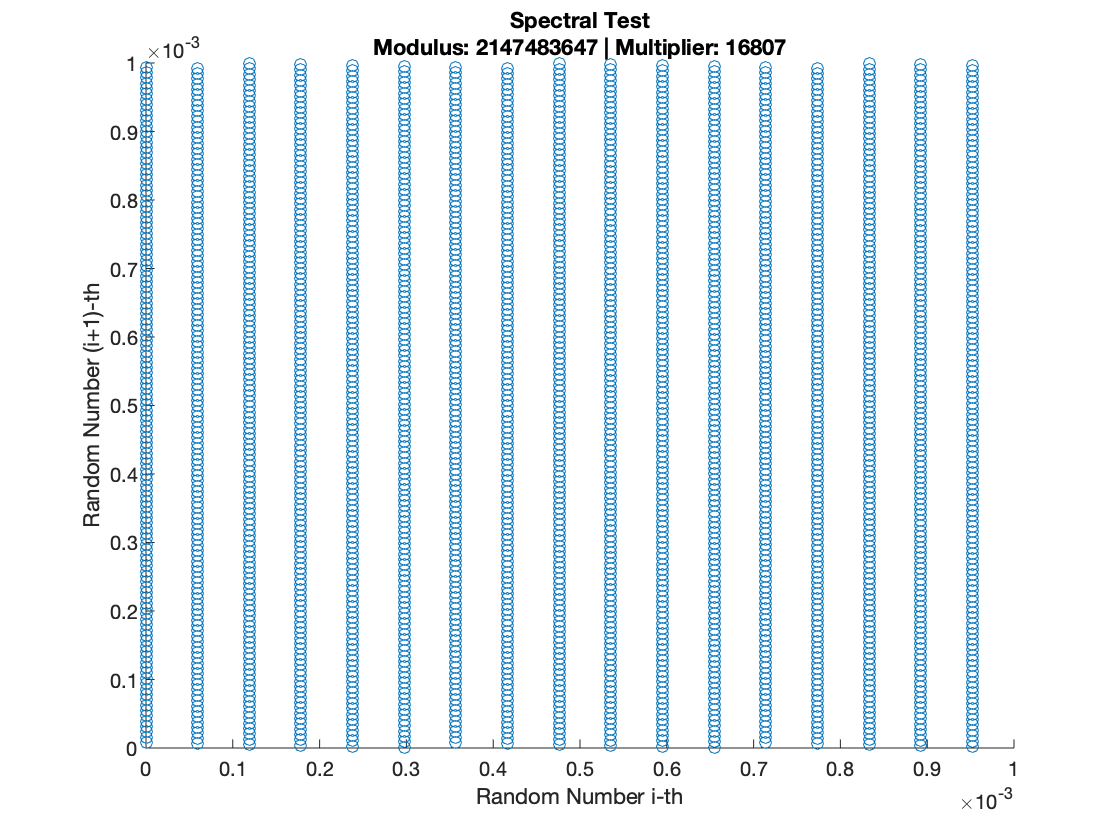

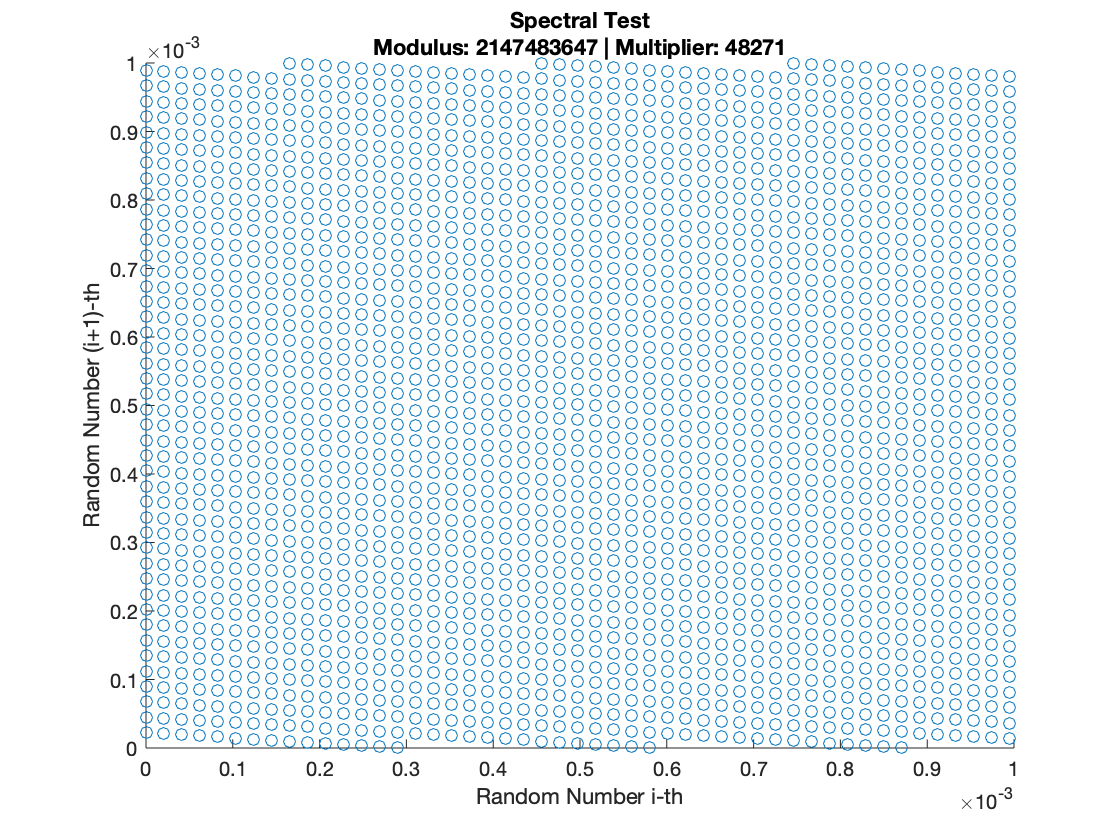

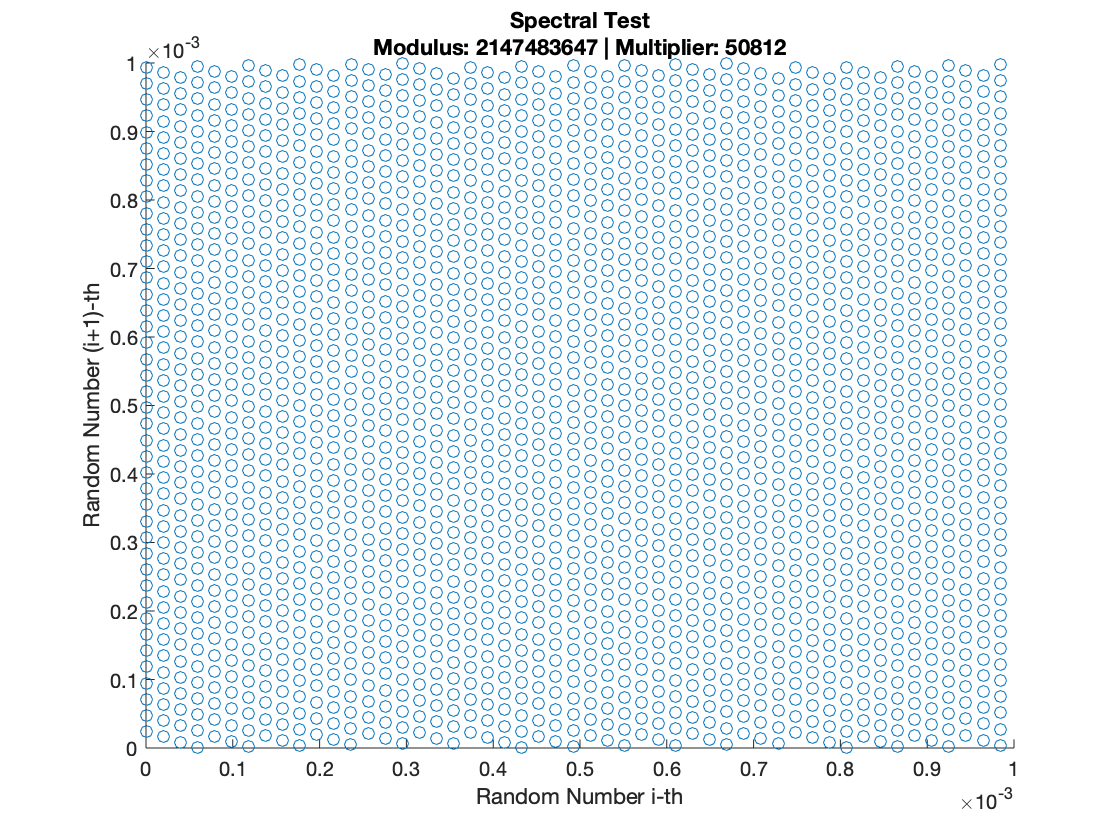

for multiplier = multipliers
    data = readtable(sprintf("out/spectral/mod%d_mul%d.csv", modulus, multiplier));
    
    x = data.u1;
    y = data.u2;
    
    scatter(x, y);
    title({"Spectral Test";sprintf("Modulus: %d | Multiplier: %d", modulus, multiplier)});
    xlabel("Random Number i-th");
    ylabel("Random Number (i+1)-th");
    figure;
end

`Test of Extremes`

`Let us see the results obtained with the Test of Extremes.`

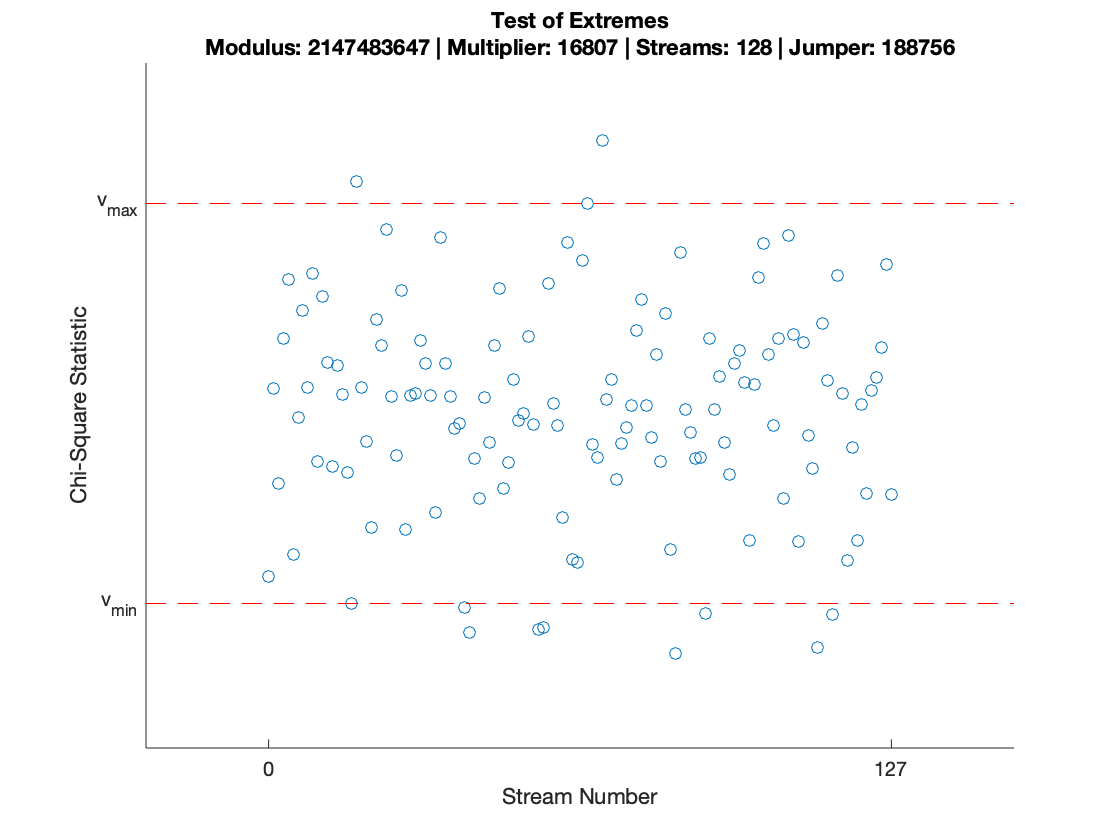

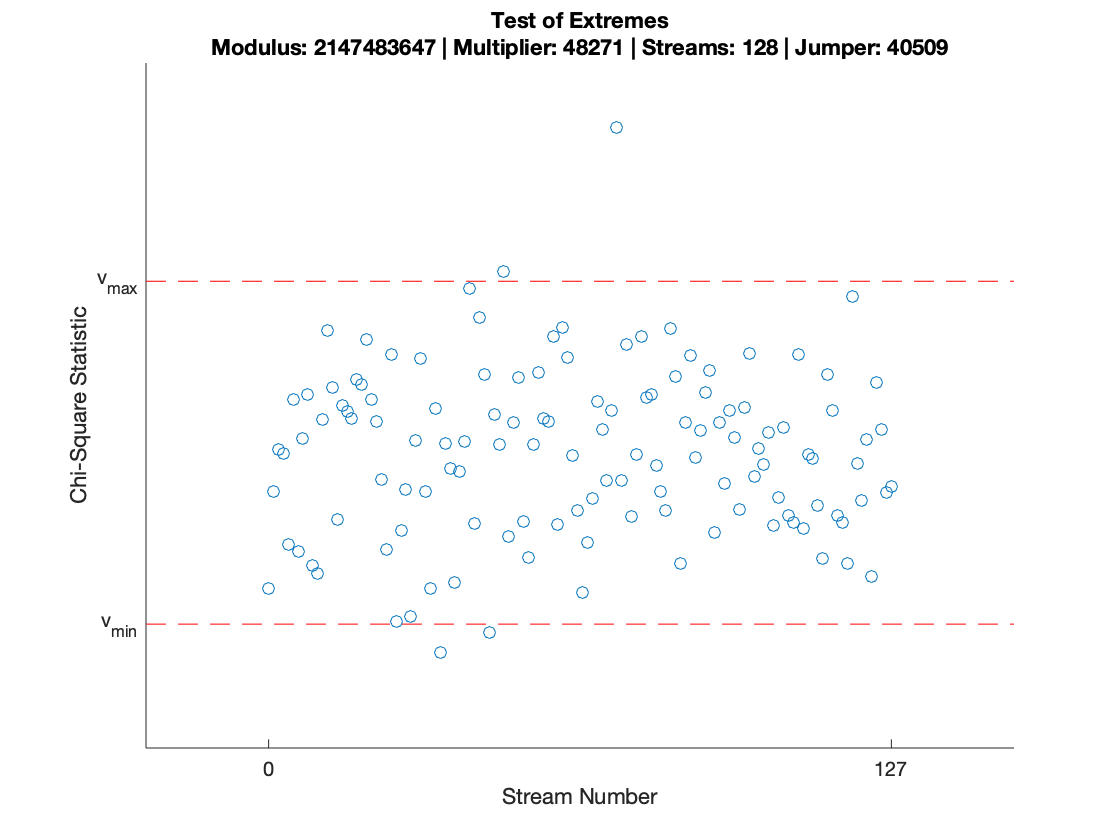

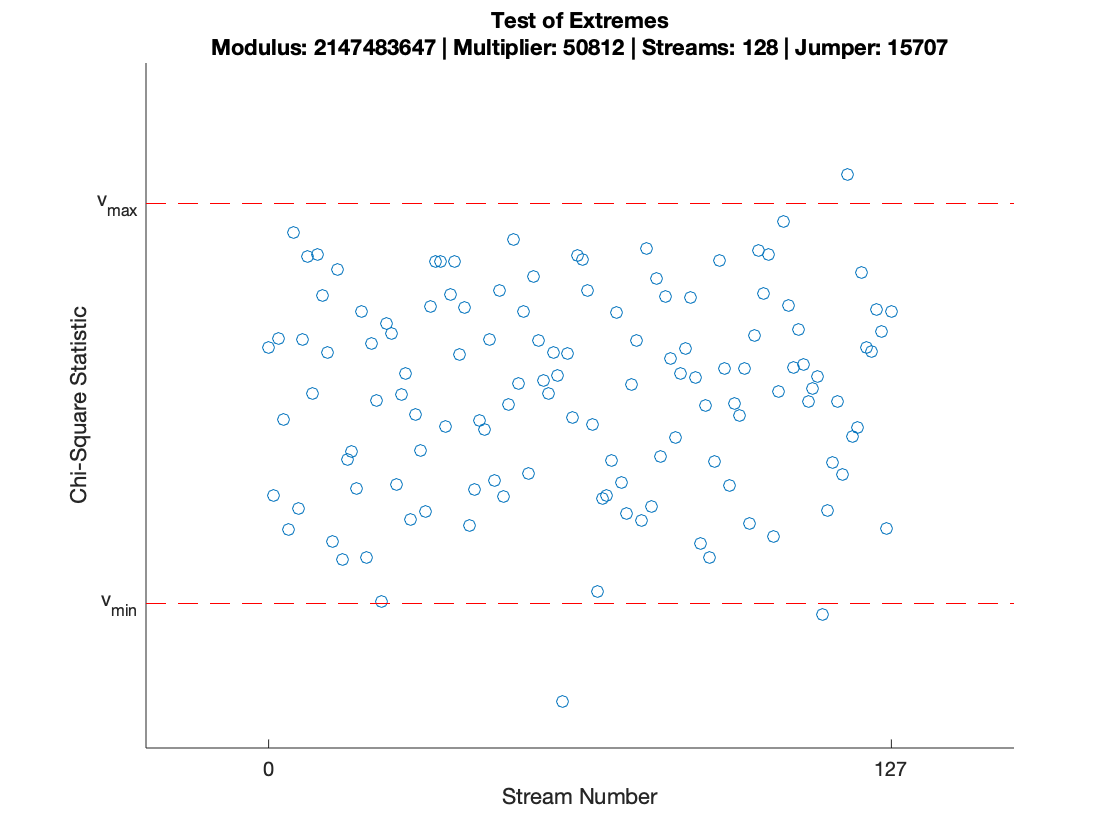

for multiplier = multipliers
    data = readtable(sprintf('out/extremes/mod%d_mul%d_str%d.csv', modulus, multiplier, streams));
    report = readtable(sprintf('out/extremes/mod%d_mul%d_str%d_report.csv', modulus, multiplier, streams));
    
    x = data.stream;
    y = data.value;
    
    criticalLower = report.critical_bounds_lower_bound;
    criticalUpper = report.critical_bounds_upper_bound;
    jumper = report.generator_jumper;
    
    %streams = length(x);
    offset = 25;
    
    scatter(x, y);
    hold on
    plot([-offset streams-1+offset], [1 1] * criticalLower, '--r')
    plot([-offset streams-1+offset], [1 1] * criticalUpper, '--r')
    hold off
    title({'Test of Extremes';sprintf('Modulus: %d | Multiplier: %d | Streams: %d | Jumper: %d', modulus, multiplier, streams, jumper)});
    xlabel('Stream Number');
    ylabel('Chi-Square Statistic');
    xlim([ -offset streams-1+offset ])
    set(gca,'xtick',[0 streams-1]);
    set(gca,'ytick',[criticalLower criticalUpper]);
    yticklabels({'v_{min}', 'v_{max}'});
    figure;
end

`Kolmogorov-Smirnov Analysis`

`Let us see the results obtained with the Kolmogorov-Smirnov Analysis.`

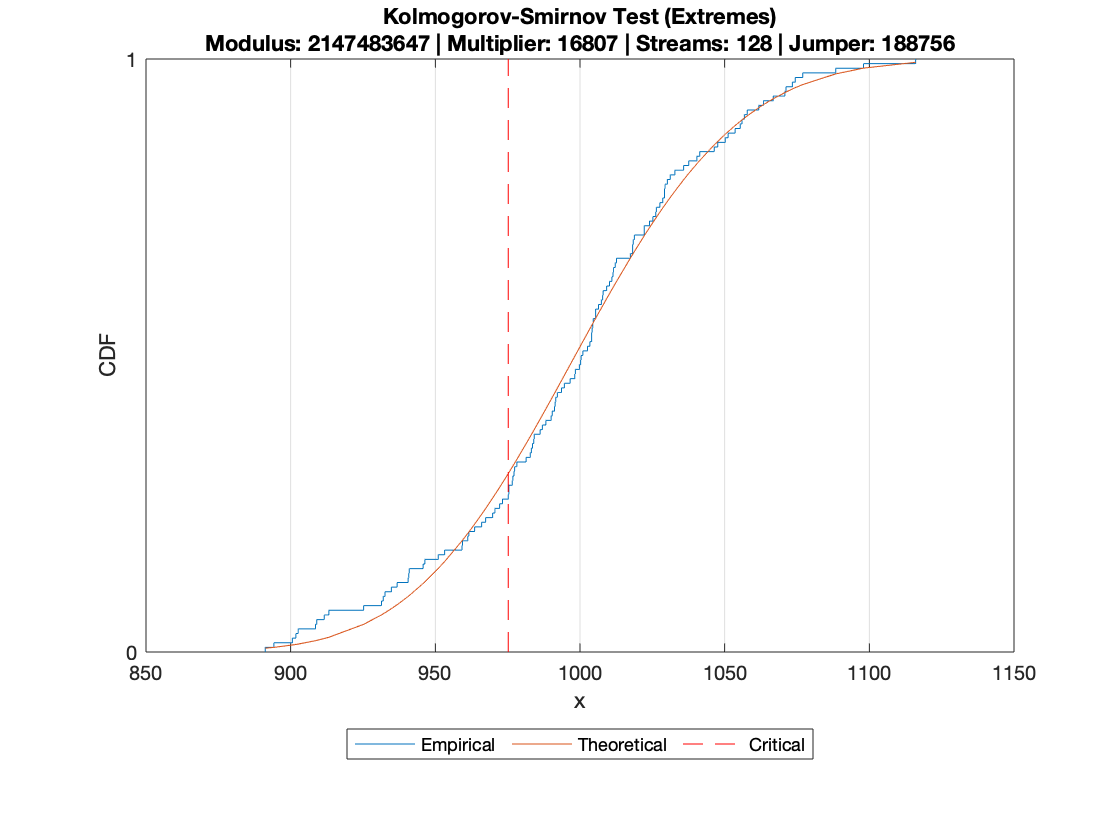

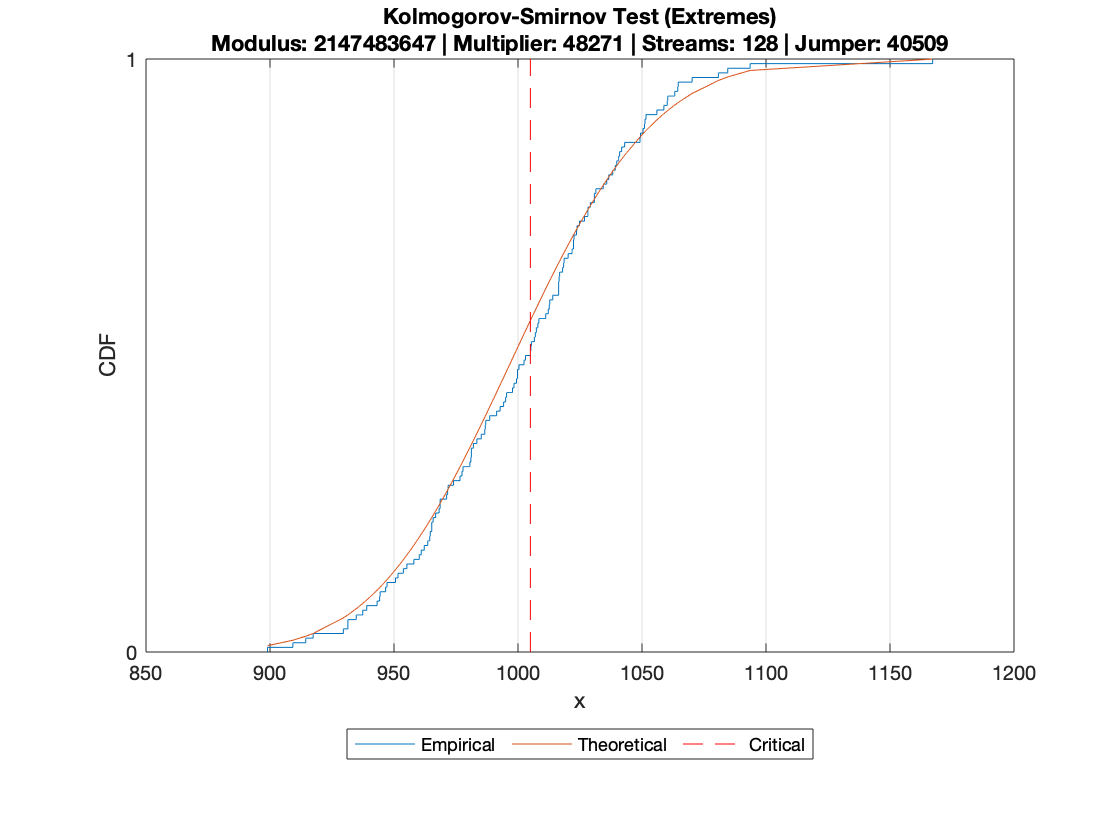

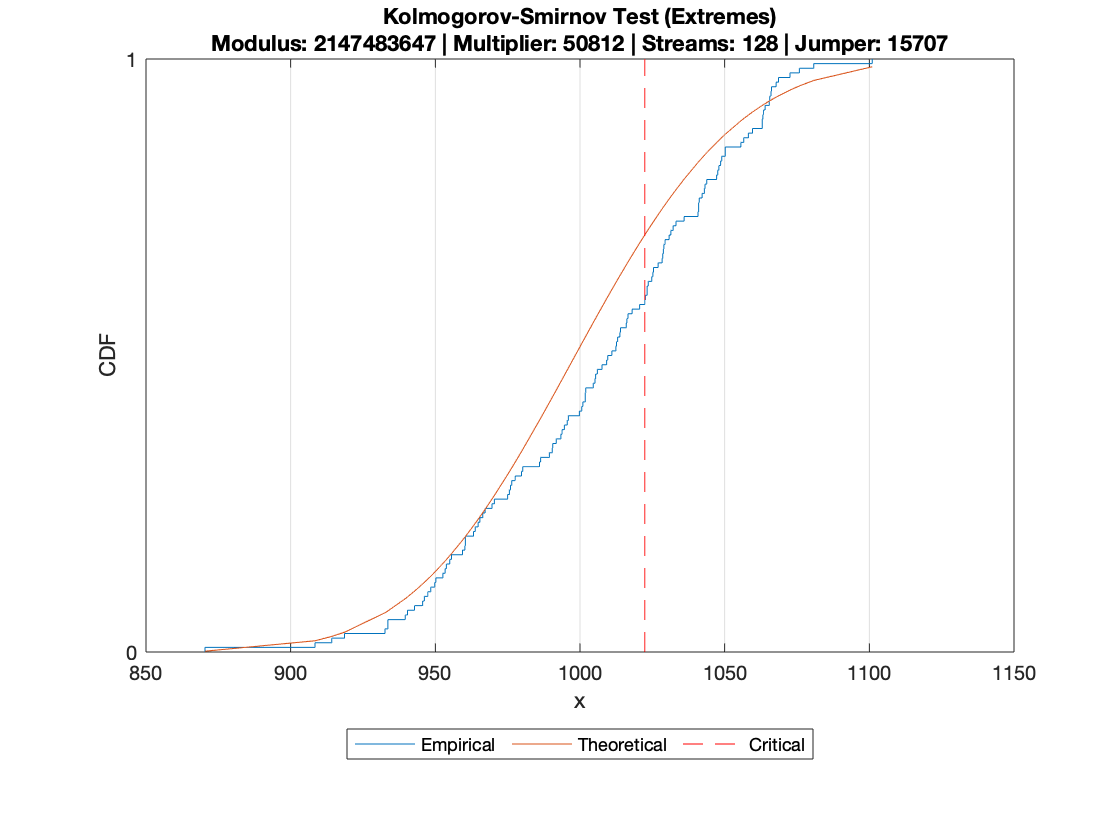

for multiplier = multipliers
    data = readtable(sprintf('out/kolmogorov-smirnov/extremes/mod%d_mul%d_str%d.csv', modulus, multiplier, streams));
    report = readtable(sprintf('out/kolmogorov-smirnov/extremes/mod%d_mul%d_str%d_report.csv', modulus, multiplier, streams));
    
    bins = report.test_parameters_bins;
    jumper = report.generator_jumper;
    critical = report.ks_ks_point_x;
    
    empirical = sort(data.value);
    theoretical = chi2cdf(empirical, bins - 1);
    
    cdfplot(empirical)
    hold on
    plot(empirical, theoretical)
    plot([1 1] * critical, [0.0 1.0], '--r')
    hold off
    title({'Kolmogorov-Smirnov Test (Extremes)';sprintf('Modulus: %d | Multiplier: %d | Streams: %d | Jumper: %d', modulus, multiplier, streams, jumper)});
    xlabel('x');
    ylabel('CDF');
    set(gca,'ytick',[0.0 1.0]);
    legend('Empirical', 'Theoretical', 'Critical', 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end

## `Transient Analysis`

`Let us now study the transient period of the simulated system.`

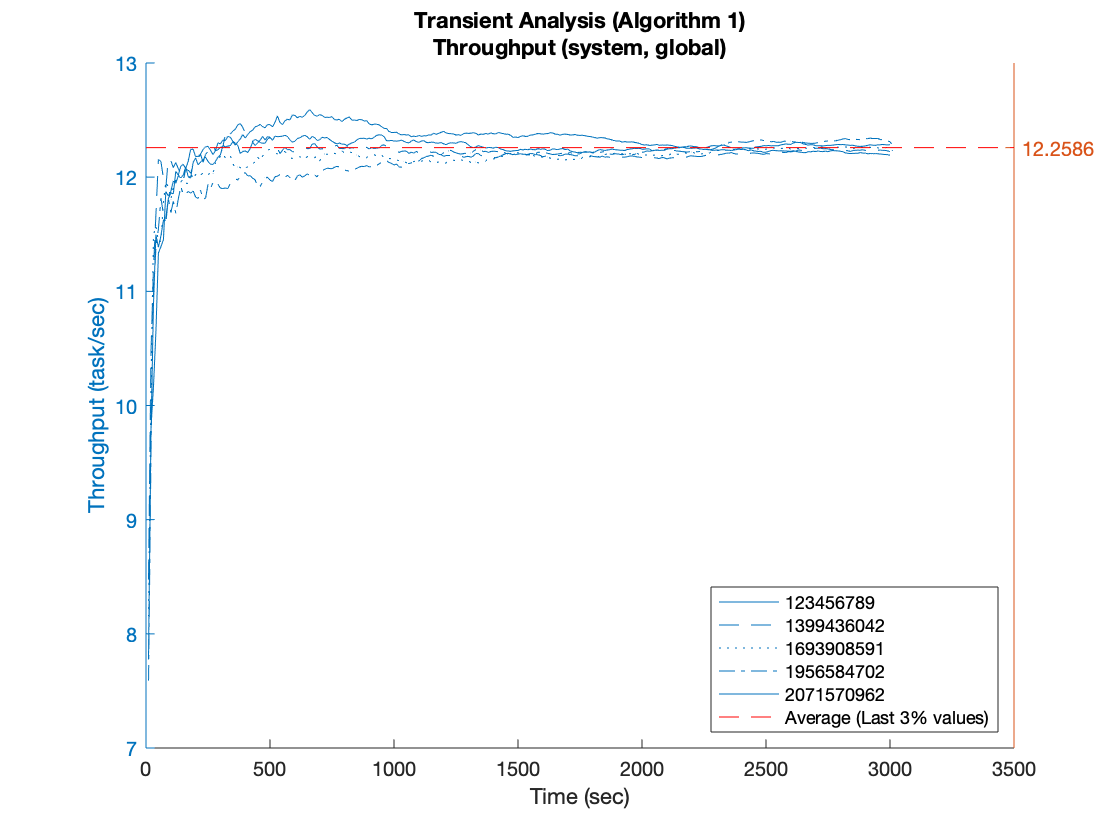

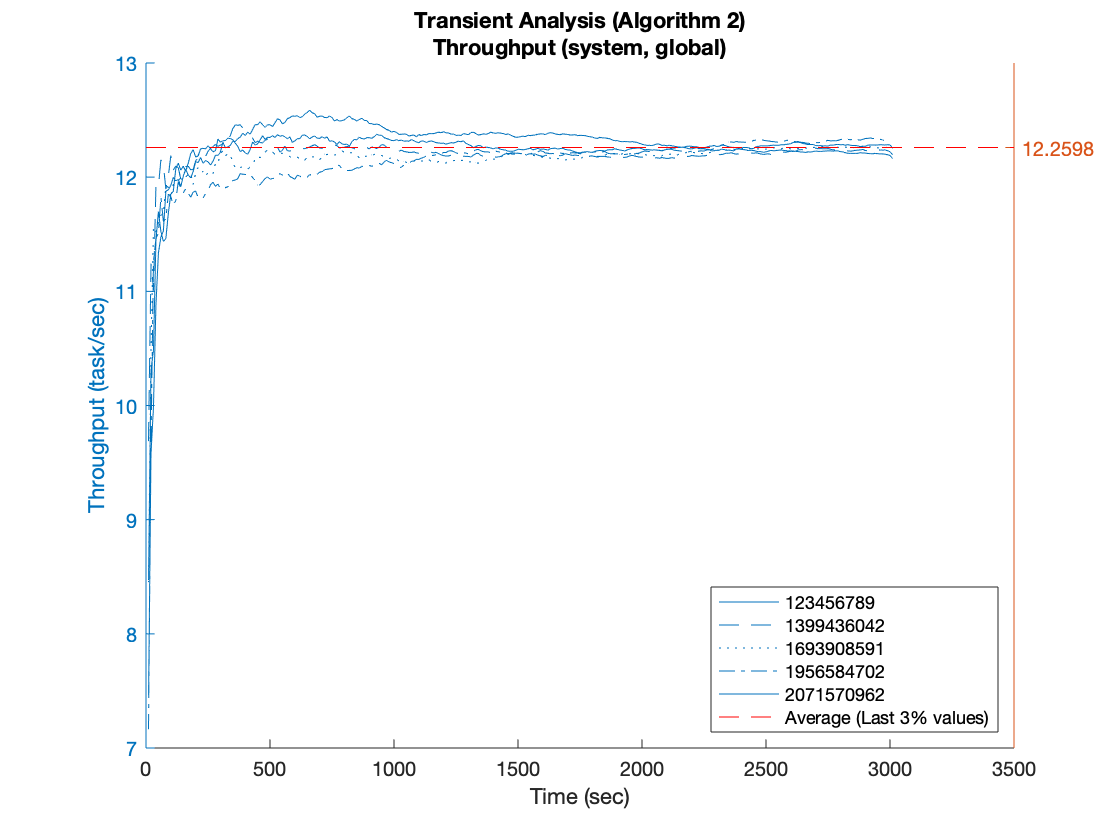

metrics   = ["throughput"]; % ["response", "throughput", "population"];
sysScopes = ["system"]; % ["system", "cloudlet", "cloud"];
tskScopes = ["global"]; % ["global", "task_1", "task_2"];
units     = ["task/sec"]; % ["sec/task", "task/sec", "task", "ratio", "sec/task"];
headings  = ["Throughput"]; % ["Response Time", "Throughput", "Mean Population"];

algorithms = ["1","2"];

portionOfLastValuesToConsiderForMean = 0.03;

for a = 1:length(algorithms)
    algorithm = algorithms(a);
    
    ls = dir(sprintf('out/transient_analysis/algorithm_%s/seed_*', algorithm));
    seeds = strrep(string({ls.name}.'),'seed_','');
    
    for m = 1:length(metrics)
        for s = 1:length(sysScopes)
            for t = 1:length(tskScopes)
                metric = metrics(m);
                sys    = sysScopes(s);
                tsk    = tskScopes(t);
                unit   = units(m);
                
                heading = sprintf("%s (%s, %s)", headings(m), sys, tsk);
                entry   = sprintf("%s_%s_%s", metric, sys, tsk);
                
                title({sprintf('Transient Analysis (Algorithm %s)', algorithm), heading});
                xlabel('Time (sec)');
                ylabel(sprintf('%s (%s)', headings(m), unit));
                legend('show', 'Location', 'southeast', 'Orientation', 'vertical');
                
                valuesForMean = [];
                
                hold on
                
                yyaxis left
                for sd = 1:length(seeds)
                    seed = seeds{sd,1};
                    data = readtable(sprintf('out/transient_analysis/algorithm_%s/seed_%s/result.sampling.csv', algorithm, seed));
                    time = data.time;
                    values = data.(char(entry));
                    
                    nValues = length(time);
                    nValuesForMean = floor(portionOfLastValuesToConsiderForMean * nValues);
                    valuesForMean = cat(1, valuesForMean, values(end-nValuesForMean:end));
                    
                    
                    plot(time, values, 'DisplayName', seed, 'Marker', 'none');
                end
                
                xl = xlim;
                yl = ylim;            
                
                avg = mean(valuesForMean);
                
                yyaxis right
                plot(xl, [avg avg], '--r', 'DisplayName', sprintf('Average (Last %d%% values)', portionOfLastValuesToConsiderForMean*100));
                ylim(yl);
                set(gca,'ytick', (avg));
                
                hold off
                
                figure;
            end
        end    
    end
end

## `Performance Analysis (simulation time, simple)`

`Let us now visualize how performance metrics behave during the simulation time, using Controller with Algorithm 1 and Algorithm 2.`

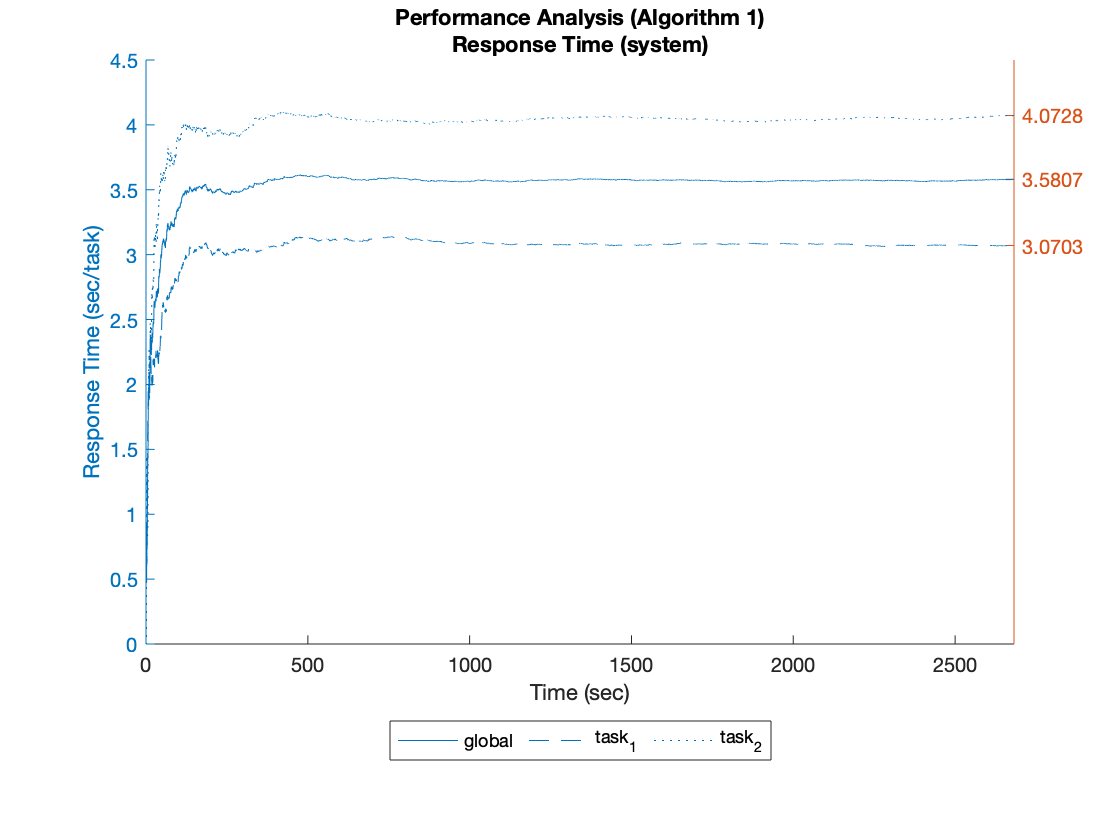

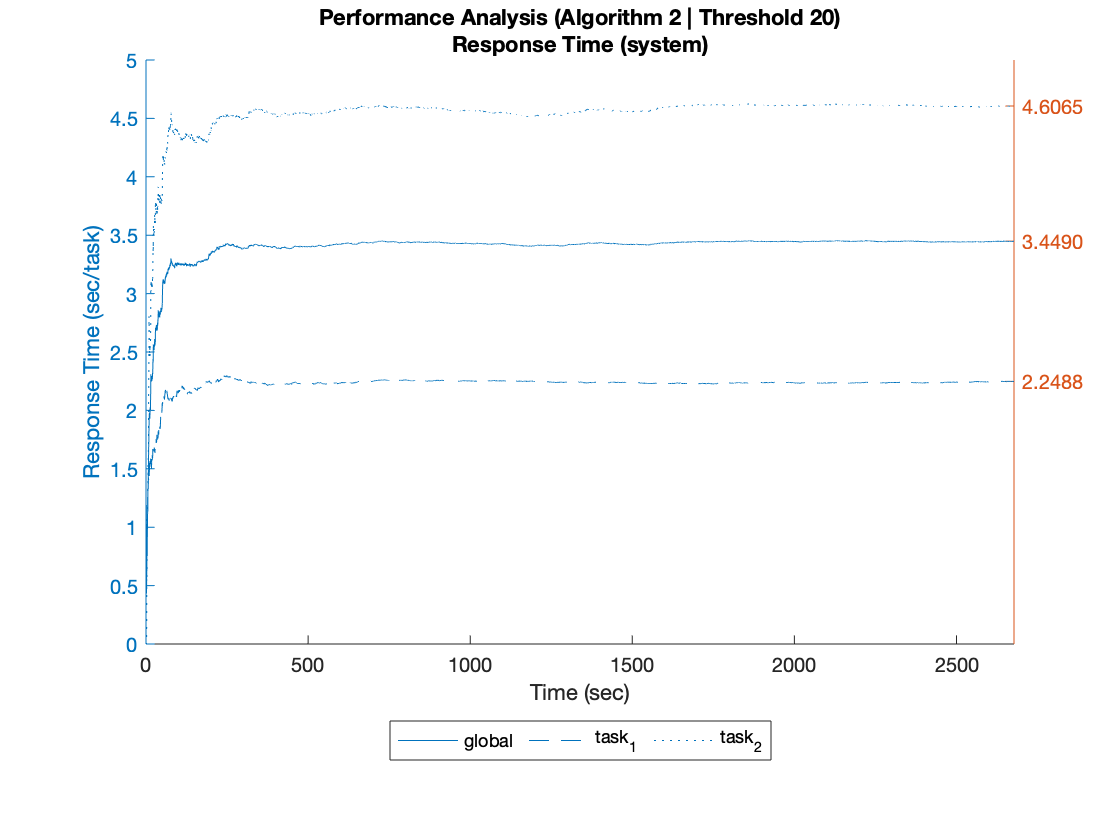

metrics   = ["response"];%["response", "throughput", "population"];
sysScopes = ["system"];
tskScopes = ["global", "task_1", "task_2"];
units     = ["sec/task", "task/sec", "task", "ratio", "sec/task"];
headings  = ["Response Time", "Throughput", "Mean Population"];

algorithms = ["1", "2"];
algorithm2Threshold = 20;

for a = 1:numel(algorithms)
    algorithm = algorithms(a);
    
    if algorithm == "1"
        plotTitle = sprintf('Performance Analysis (Algorithm %s)', algorithm);
        dataFile = sprintf('out/performance_analysis/algorithm_%s/result.sampling.csv', algorithm);
    elseif algorithm == "2"
        plotTitle = sprintf('Performance Analysis (Algorithm %s | Threshold %d)', algorithm, algorithm2Threshold);
        dataFile = sprintf('out/performance_analysis/algorithm_%s/threshold_%d/result.sampling.csv', algorithm, algorithm2Threshold);
    else
        error("Unrecognized algorithm: %s", algorithm);
    end

    data = readtable(dataFile);
    
    time = data.time;
    
    %%
    % PLOT
    %%
    
    for m = 1:length(metrics)
        for s = 1:length(sysScopes)
            metric = metrics(m);
            sys = sysScopes(s);
            unit = units(m);
            
            hold on
            heading = sprintf("%s (%s)", headings(m), sys);
            
            title({plotTitle, heading});
            xlabel('Time (sec)');
            ylabel(sprintf('%s (%s)', headings(m), unit));
            legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
            
            lastTime = time(end);
            lastValues = zeros(1,numel(tskScopes));
            xlim([0 lastTime]);
            
            for t = 1:length(tskScopes)
                tsk = tskScopes(t);
                
                ventry  = sprintf("%s_%s_%s", metric, sys, tsk);          
                
                values = data.(char(ventry));
                lastValue = tail(data,1).(char(ventry));
                lastValues(t) = lastValue;
                
                yyaxis left
                plot(time, values, 'DisplayName', sprintf('%s', tsk));
            end
            
            xl = xlim;
            yl = ylim;
                        
            yyaxis right
            
            for e = 1:numel(lastValues)
                p = plot([lastTime, xl(end)], [lastValues(e), lastValues(e)], ':r');
                set(get(get(p, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
            end
            ylim(yl);
            set(gca, 'ytick', sort(lastValues));
            hold off
            figure;
        end
    end
    
    %%
    % TABULAR
    %%
    
    %tabularFields  = repmat("", length(metrics)+1, 1);
    %tabularEntries = repmat("", length(metrics)+1, 1);
    
    %tabularFields(1) = "time";
    %tabularEntries(1) = "time";
    
    %tblIdx = 2;
    %for m = 1:length(metrics)
    %    for s = 1:length(sysScopes)
    %        for t = 1:length(tskScopes)
    %            metric = metrics(m);
    %            sys = sysScopes(s);
    %            tsk = tskScopes(t);
    %            tabularFields(tblIdx)  = sprintf("%s_%s_%s", metric, sys, tsk);
    %            tabularEntries(tblIdx) = sprintf("%s_%s_%s", metric, sys, tsk);
    %            tblIdx = tblIdx + 1;
    %        end
    %    end
    %end
    
    %tabular = data(:,cellstr(tabularEntries));
    %tabular.Properties.VariableNames = cellstr(tabularFields);
    %disp(tabular);
end

## `Performance Analysis (ALG1/ALG2, batchdim, batch means)`

`Let us now visualize how performance metrics behave during the simulation time (through batchdim), using Controller with Algorithm 1 and Algorithm 2.`

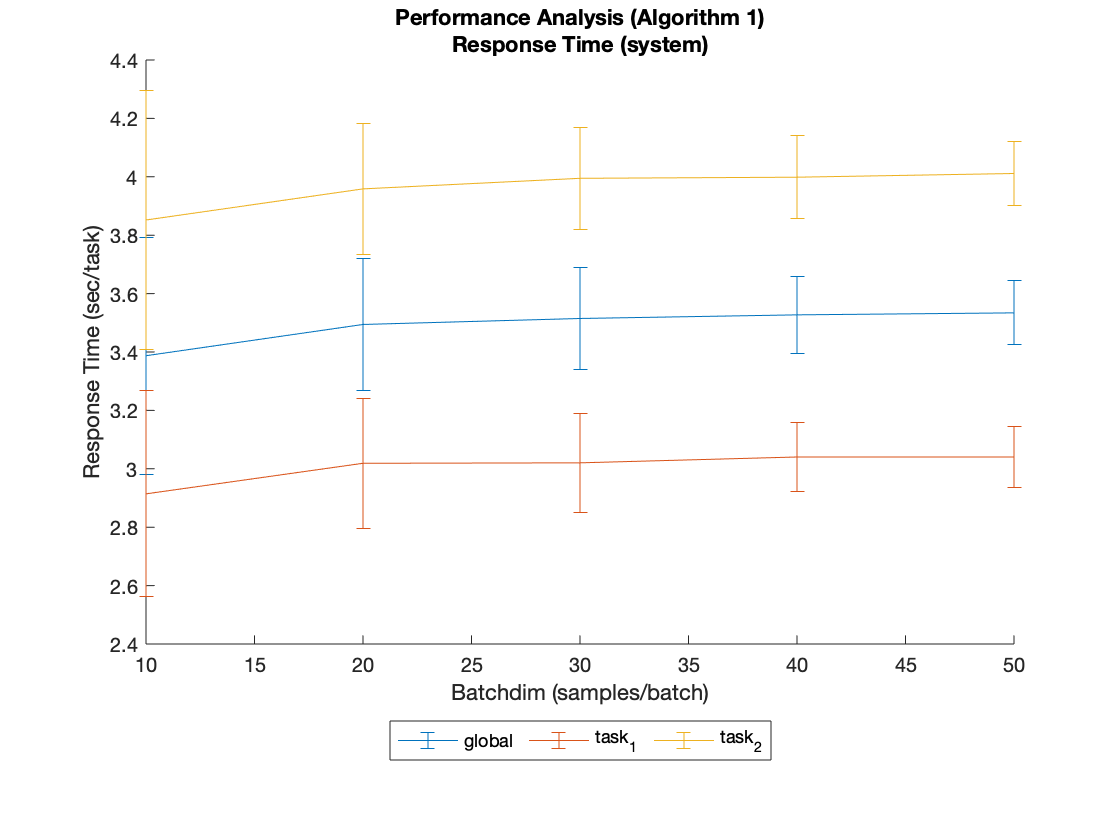

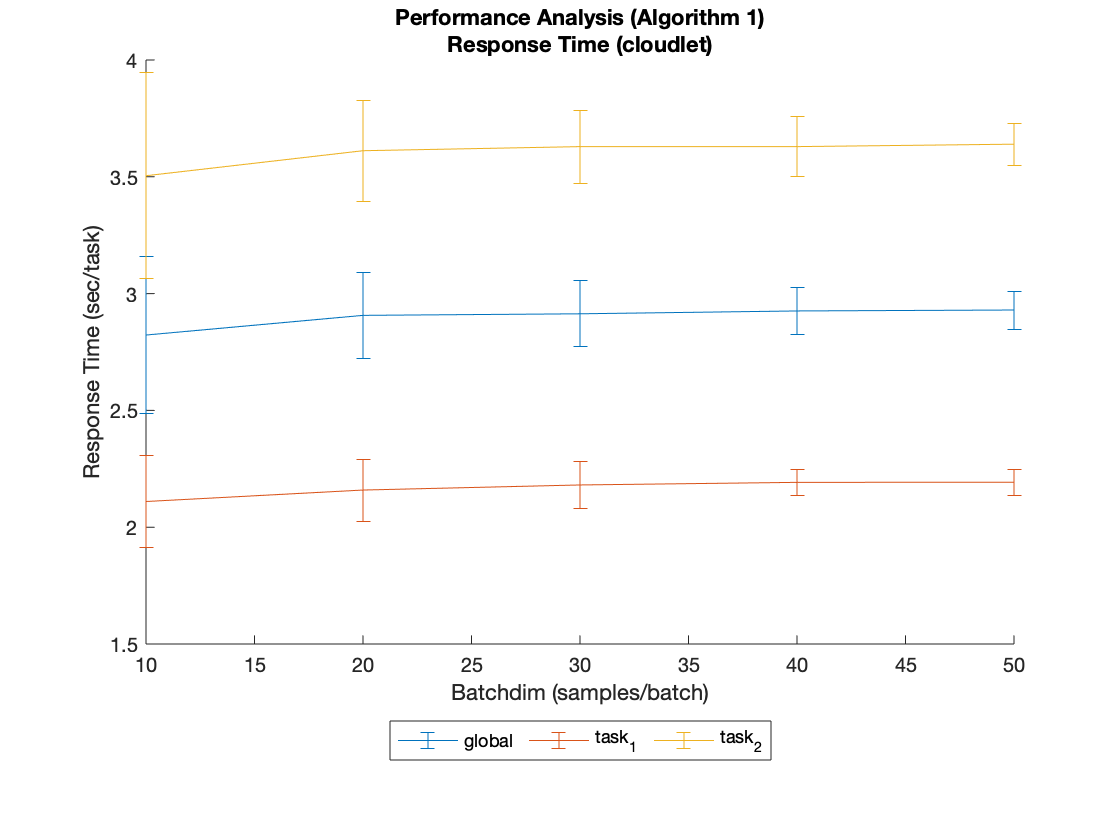

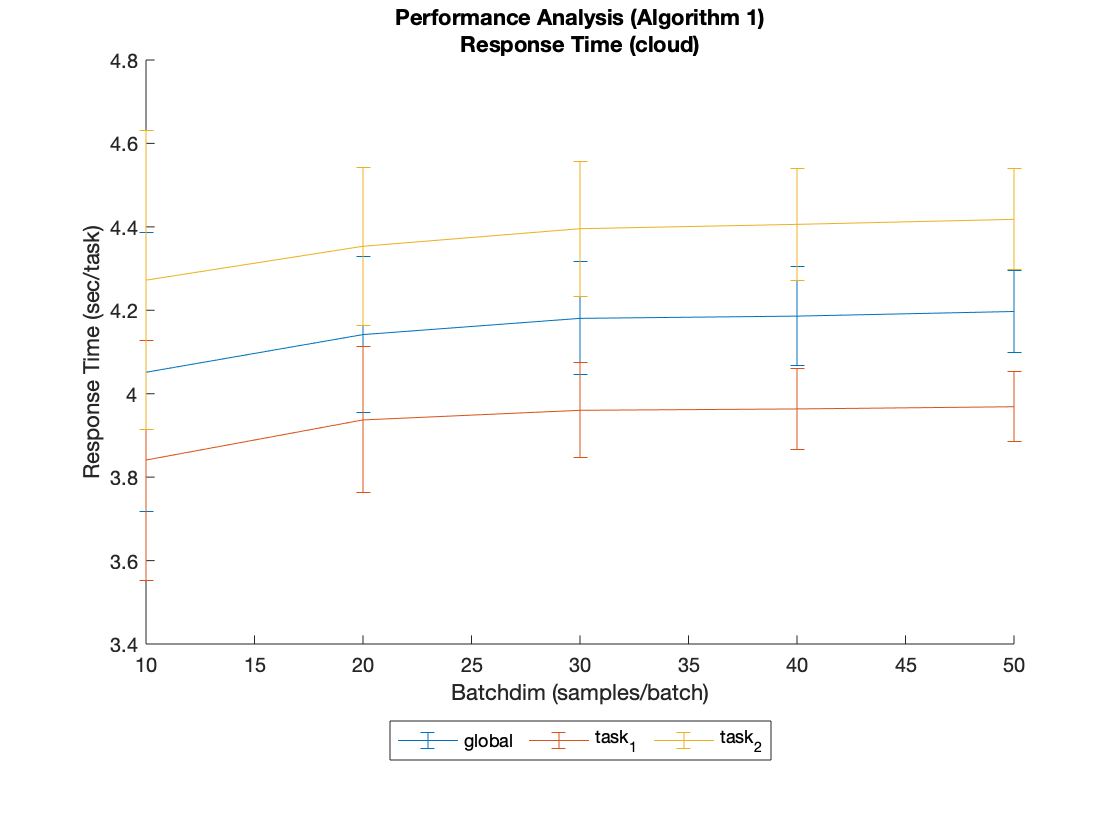

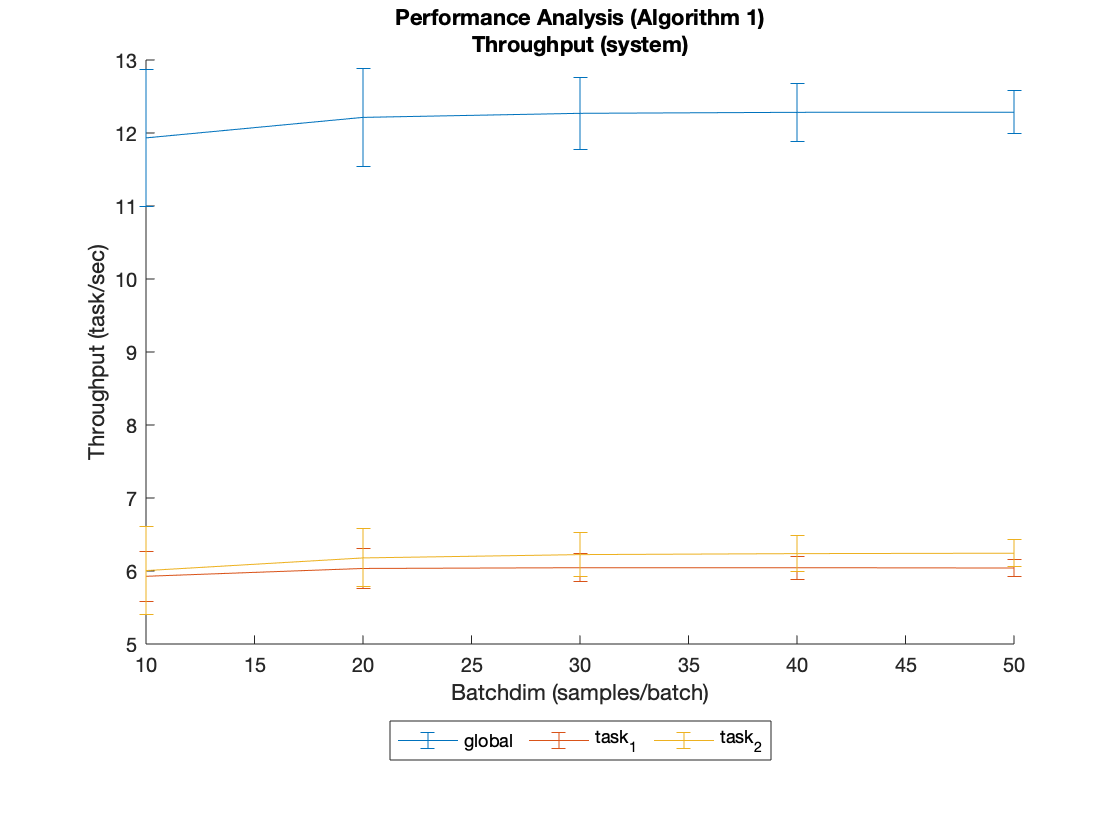

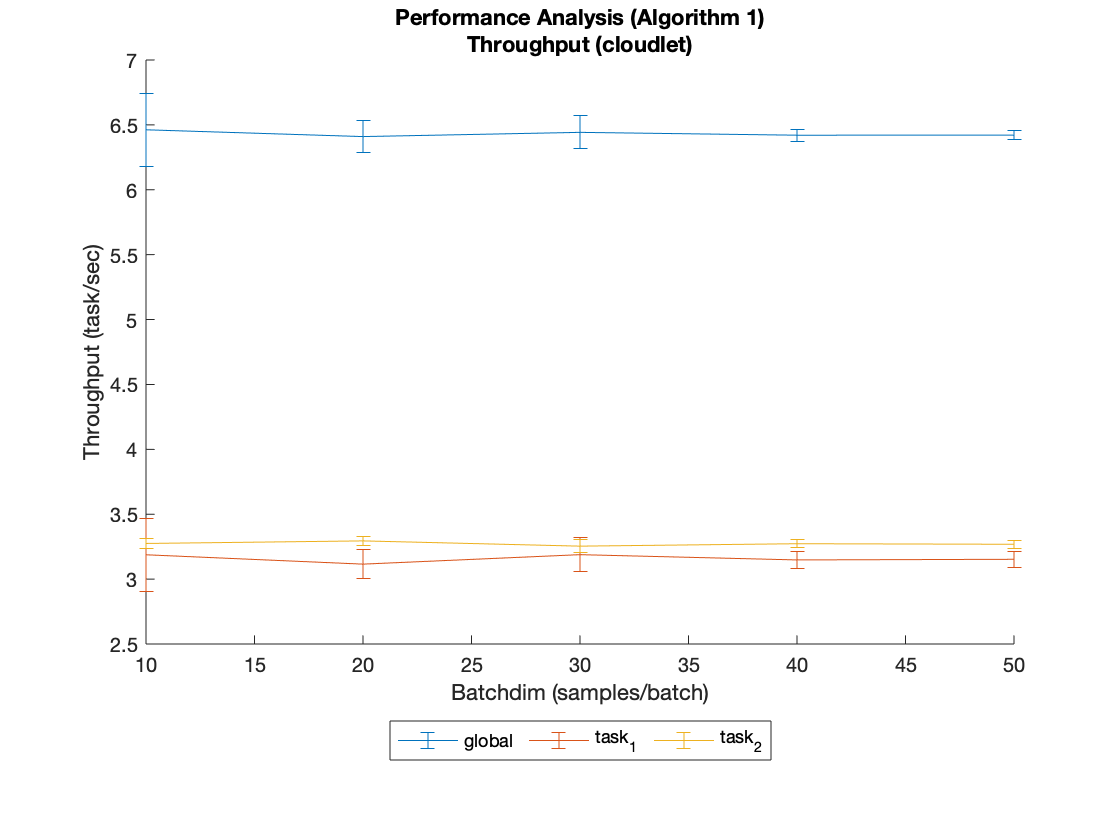

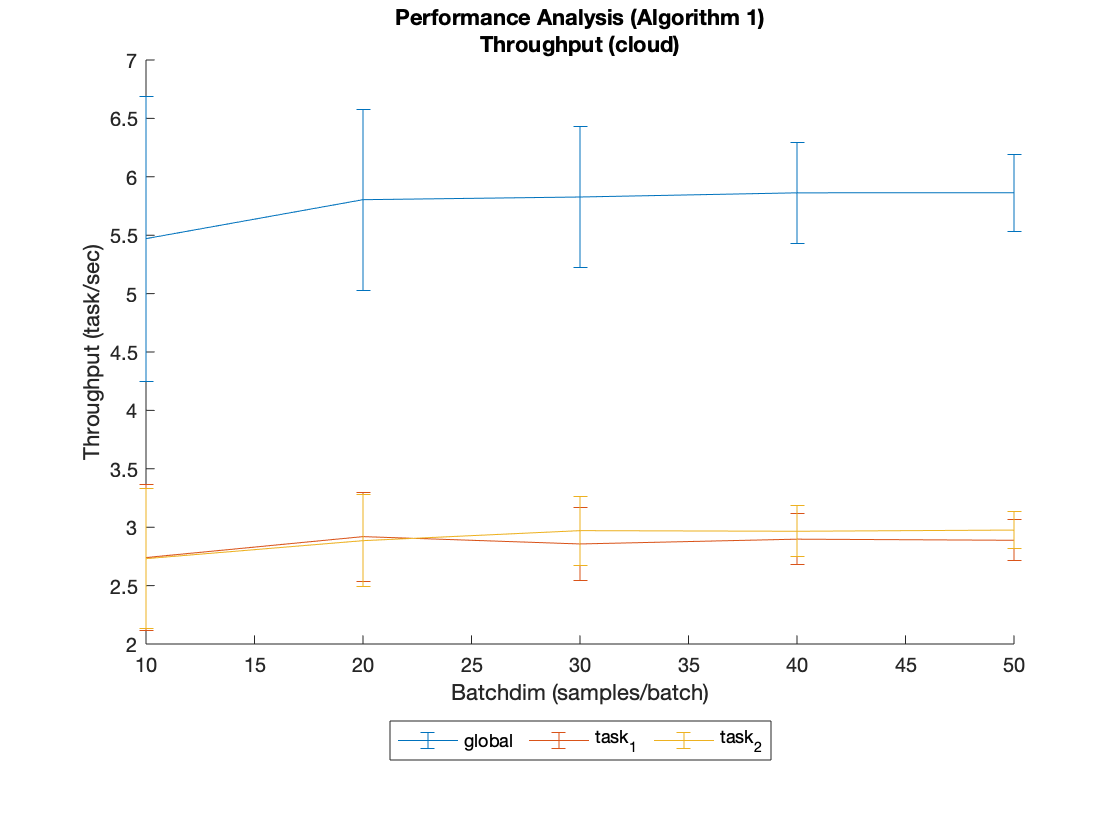

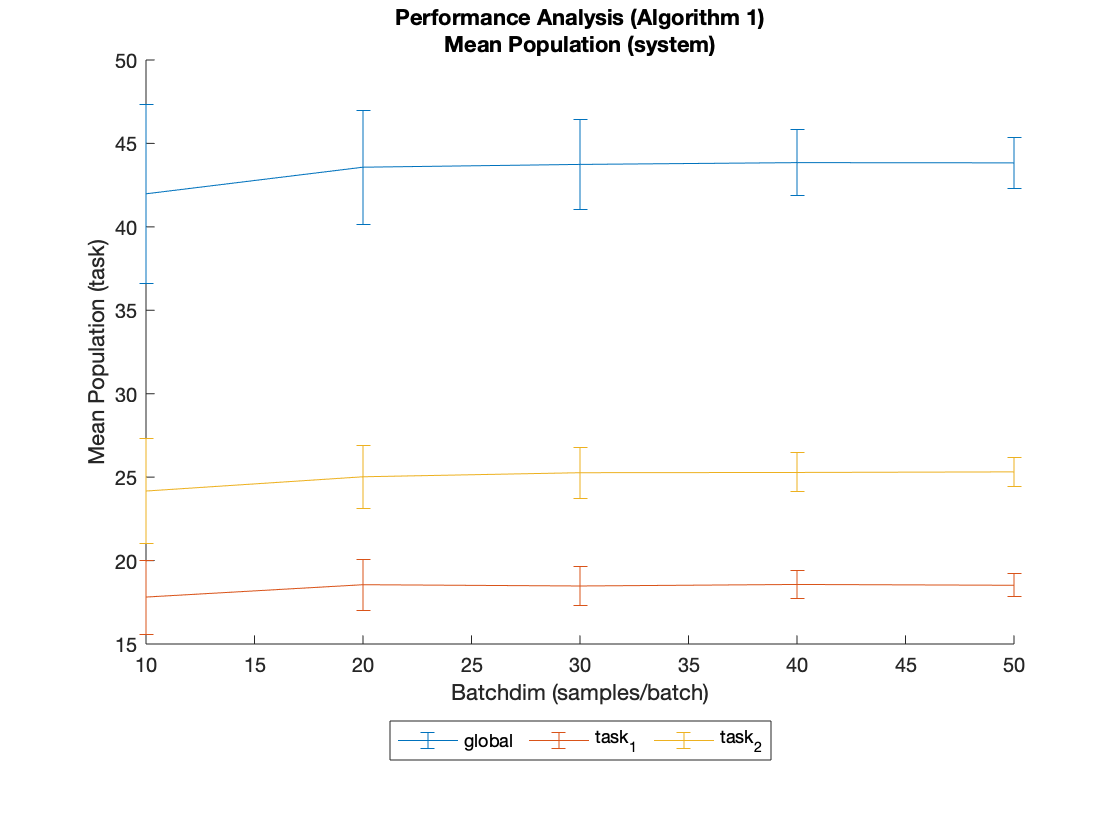

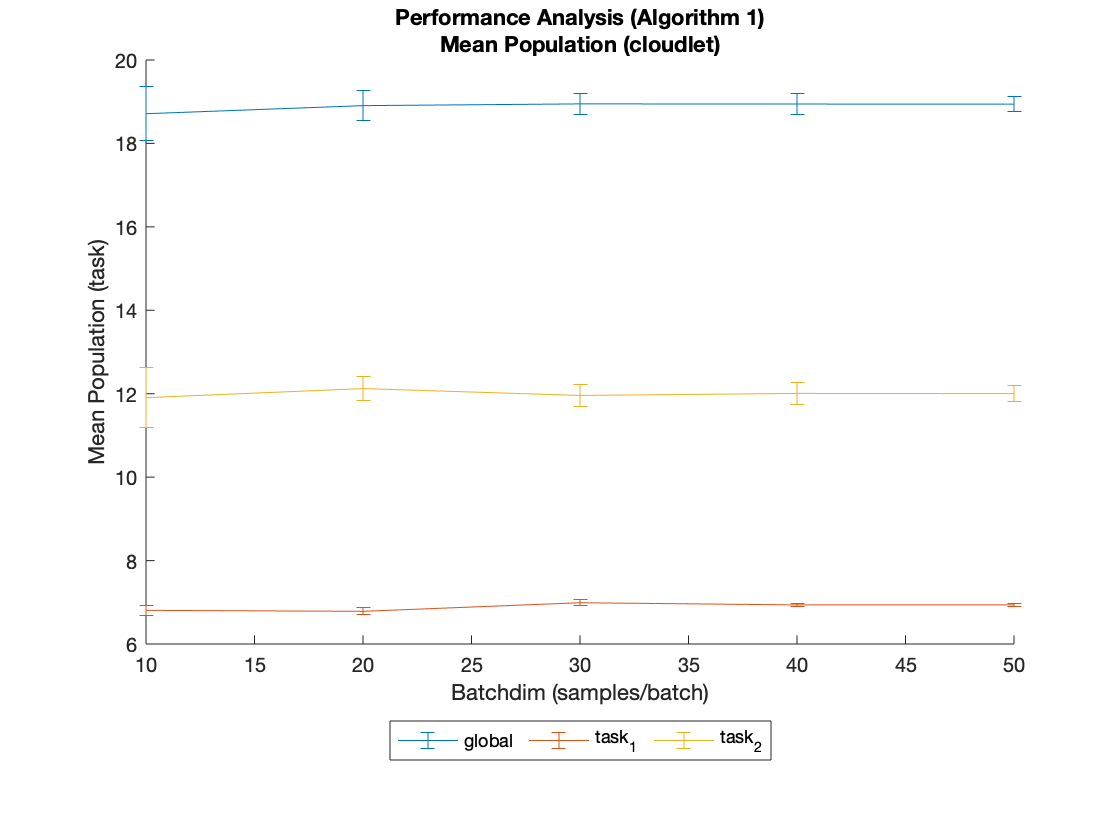

    batchdim        response_system_global             response_system_task_1             response_system_task_2            response_cloudlet_global           response_cloudlet_task_1           response_cloudlet_task_2             response_cloud_global              response_cloud_task_1              response_cloud_task_2             throughput_system_global           throughput_system_task_1           throughput_system_task_2          throughput_cloudlet_global         throughput_cloudlet_task_1         throughput_cloudlet_task_2           throughput_cloud_global            throughput_cloud_task_1            throughput_cloud_task_2            population_system_

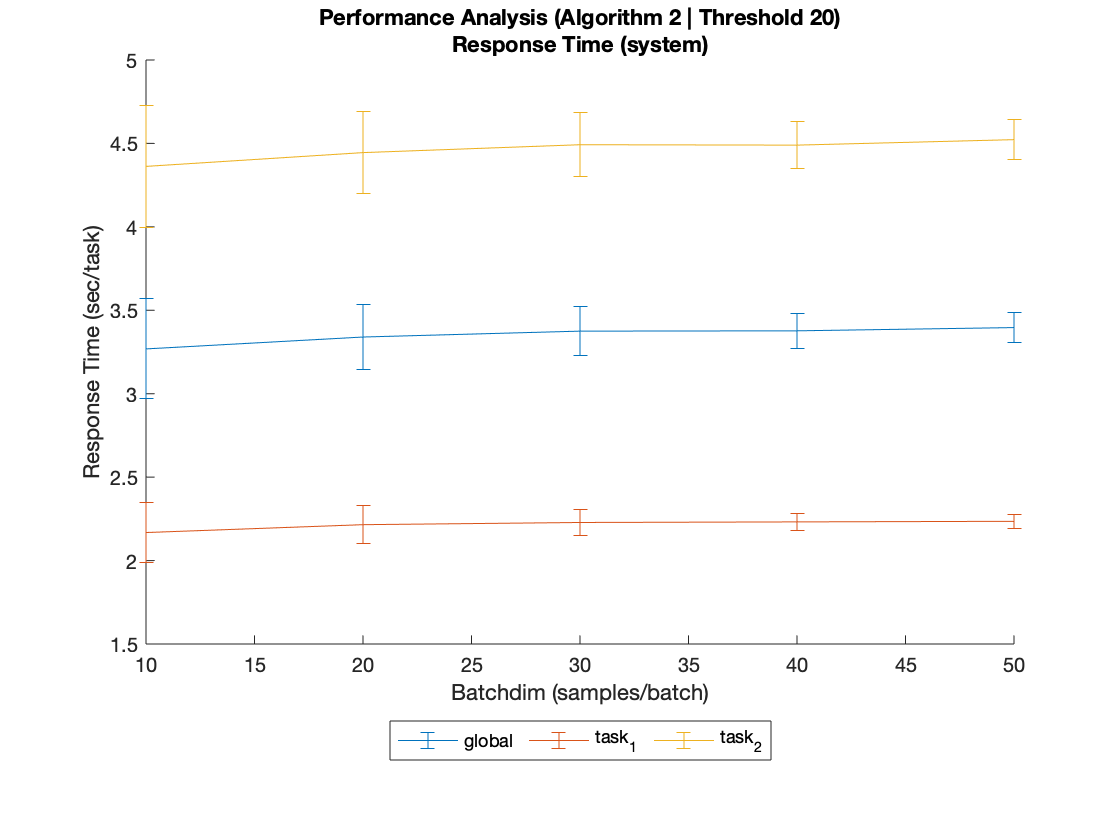

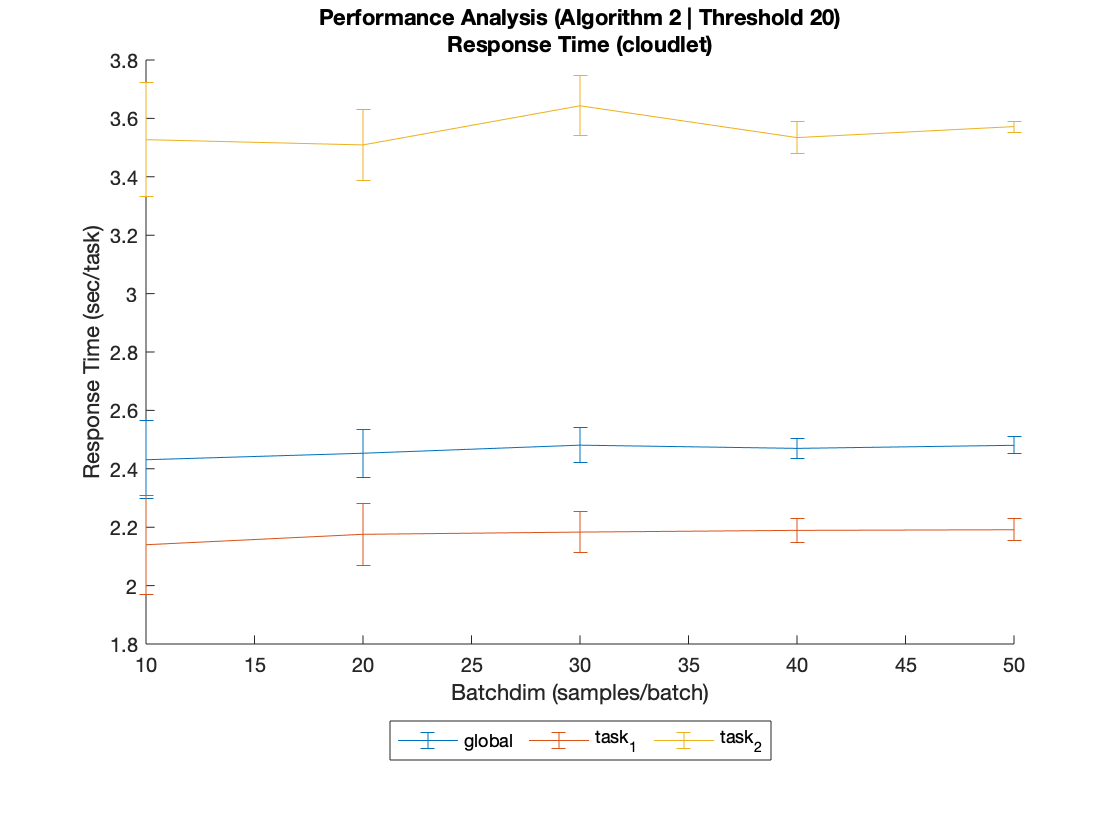

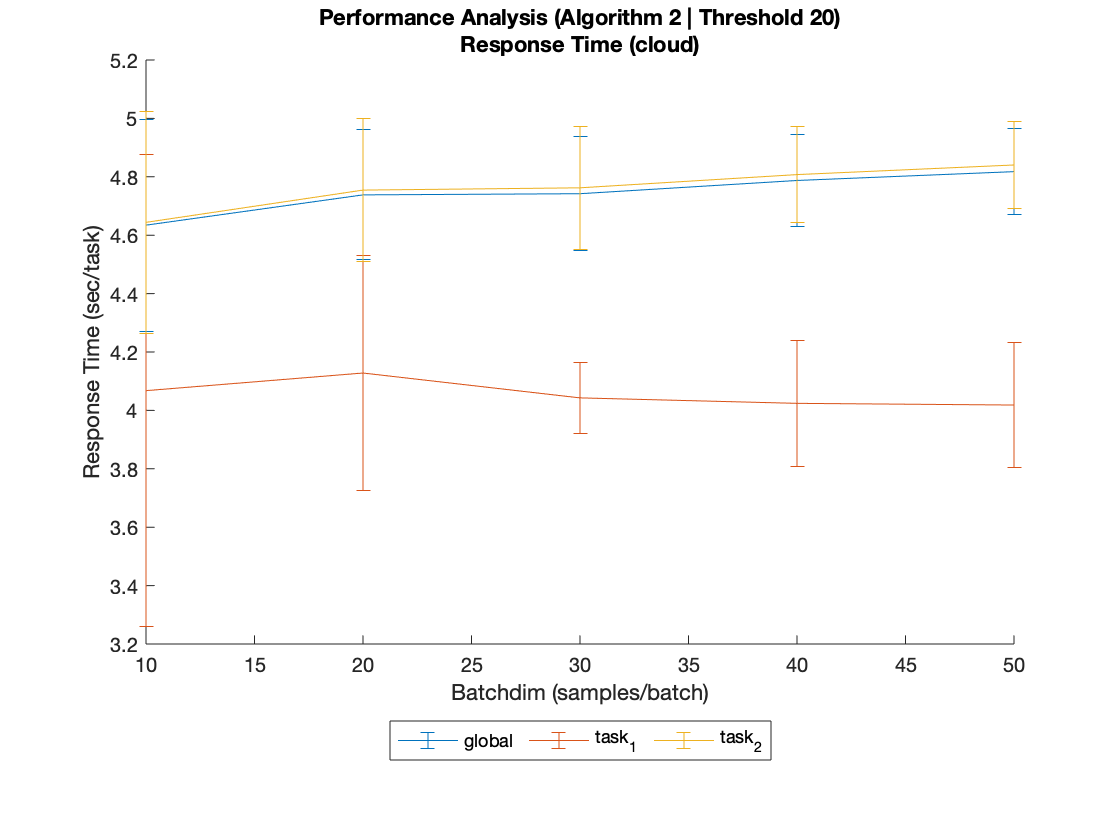

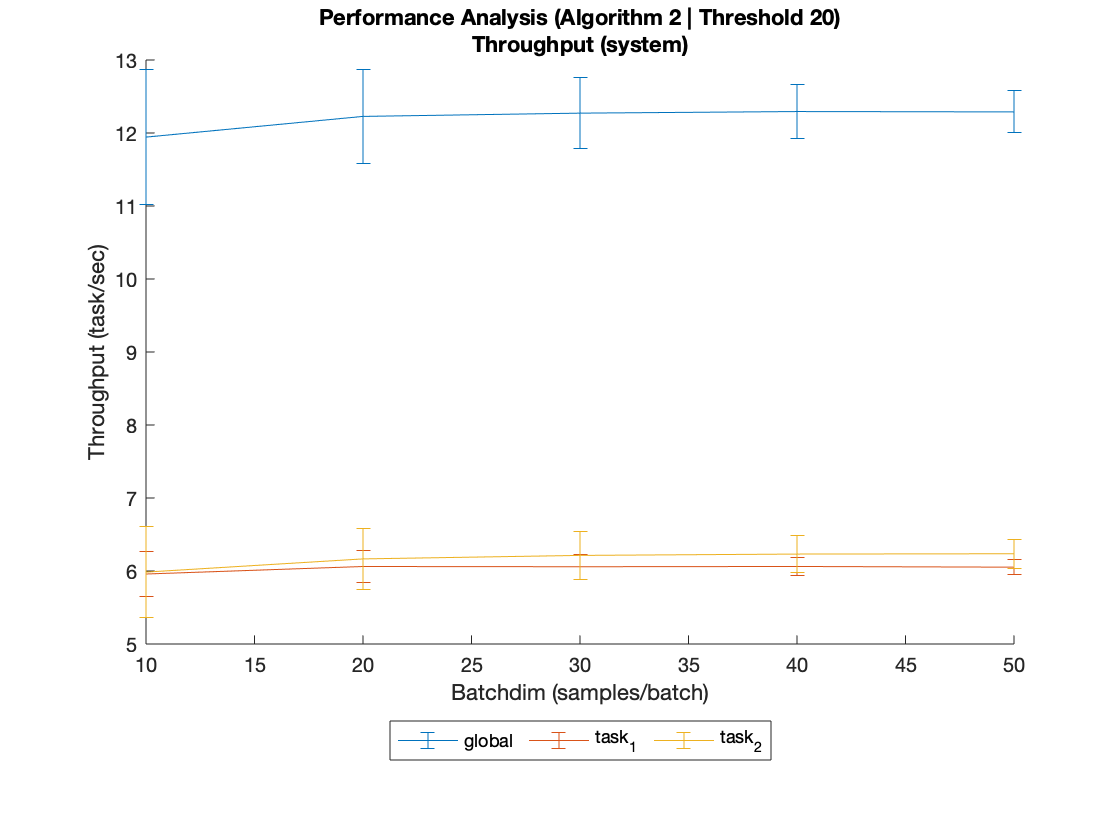

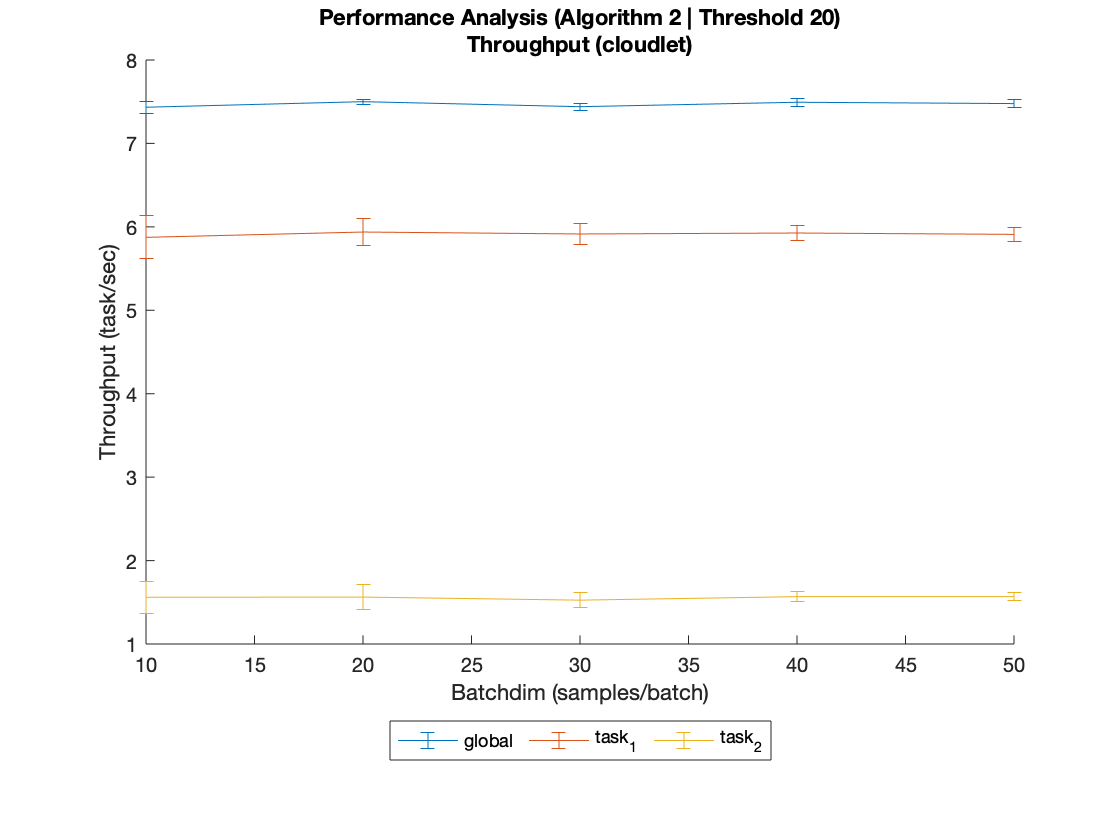

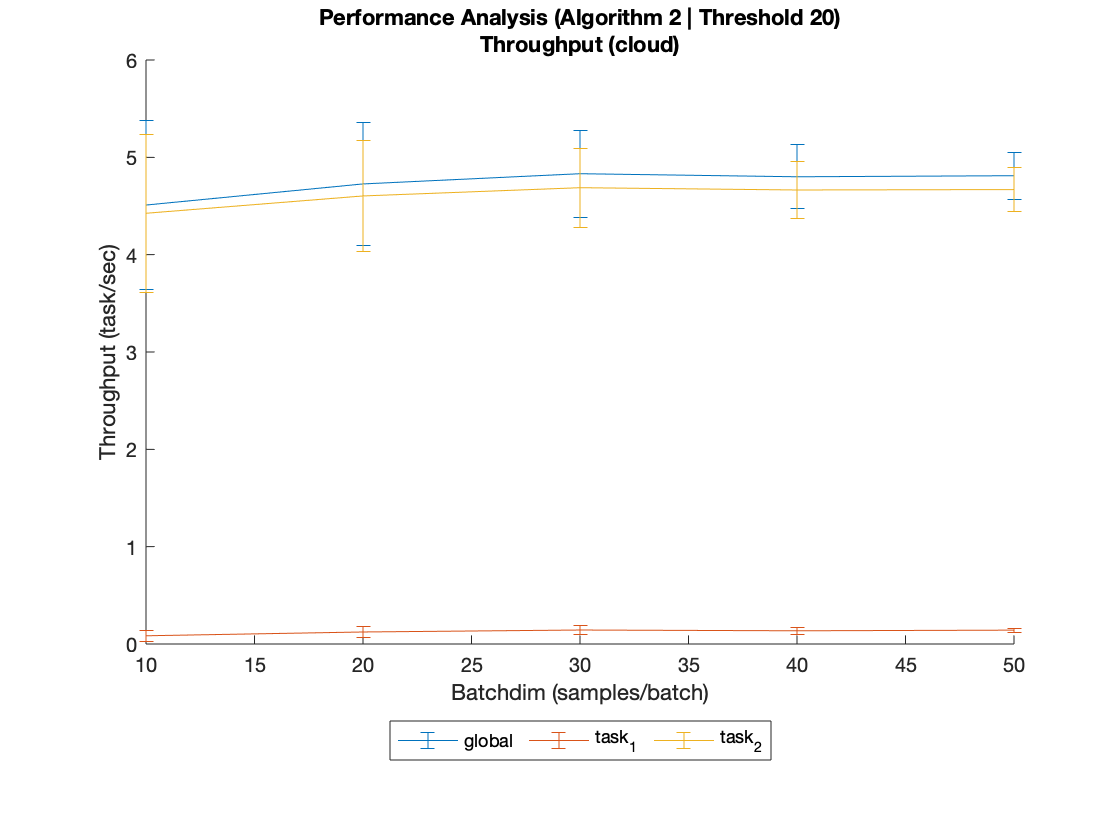

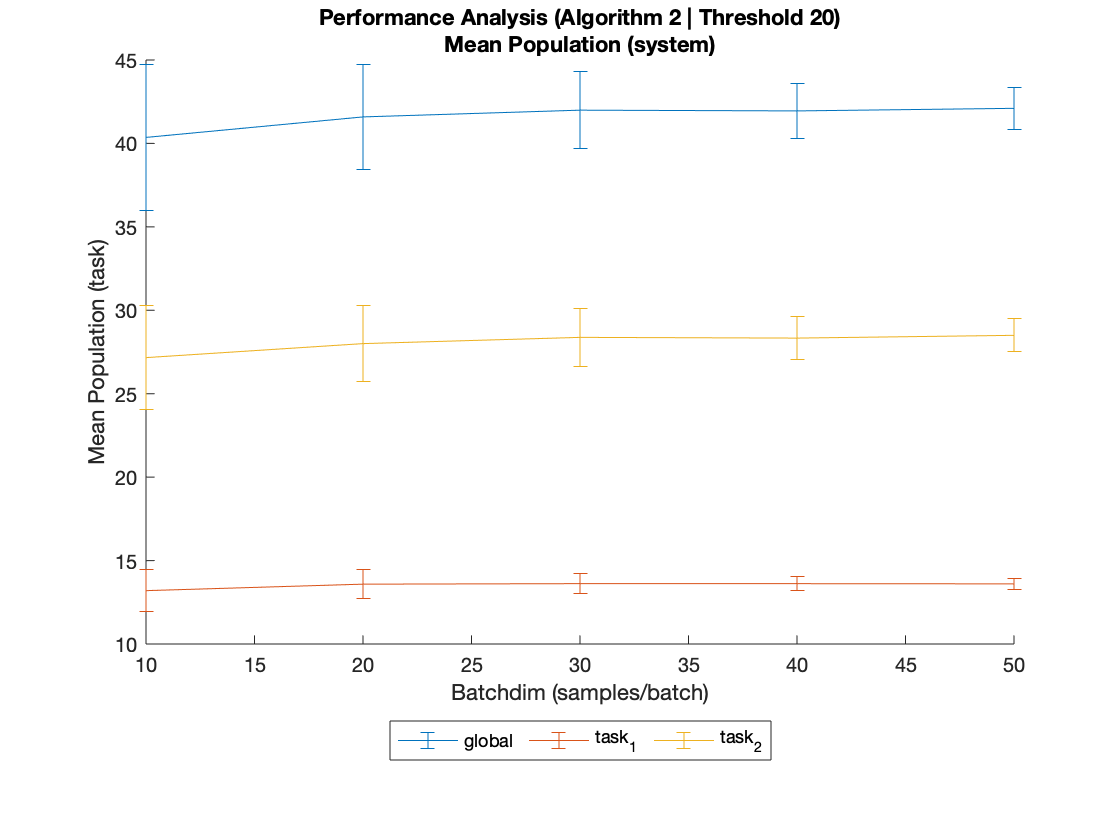

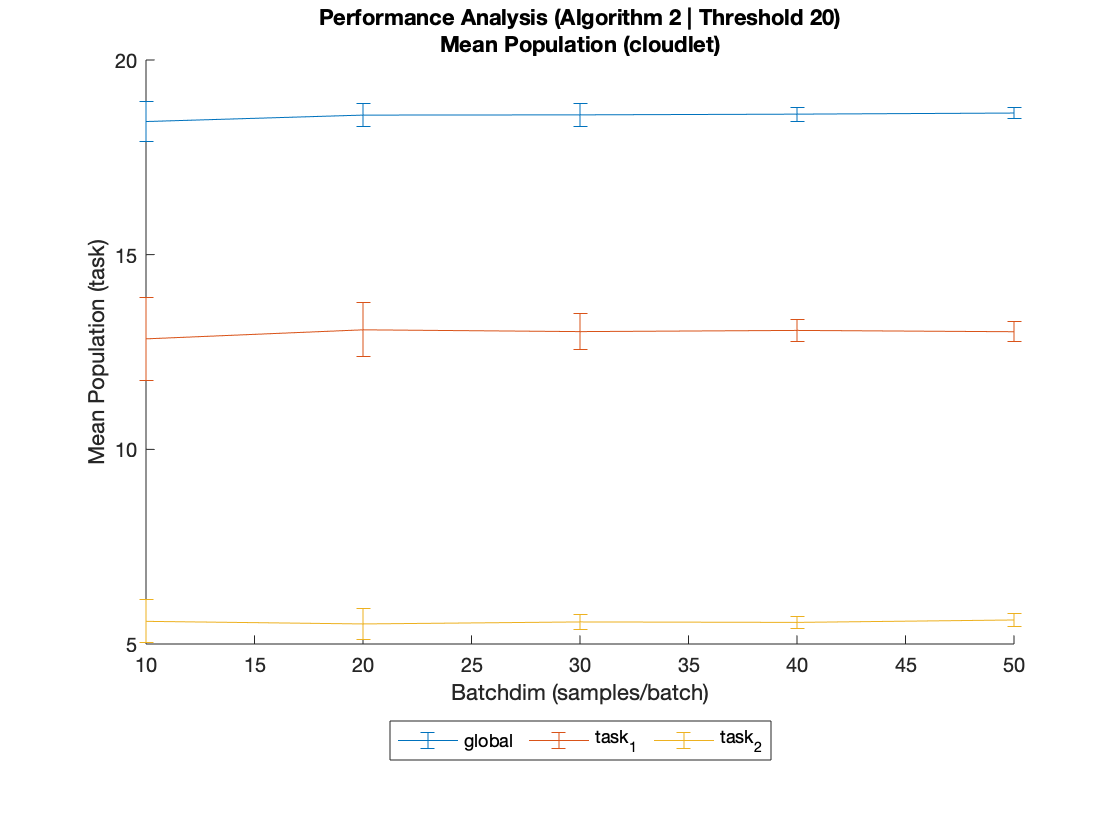

    batchdim        response_system_global             response_system_task_1             response_system_task_2            response_cloudlet_global           response_cloudlet_task_1           response_cloudlet_task_2             response_cloud_global              response_cloud_task_1              response_cloud_task_2             throughput_system_global           throughput_system_task_1           throughput_system_task_2          throughput_cloudlet_global         throughput_cloudlet_task_1         throughput_cloudlet_task_2           throughput_cloud_global            throughput_cloud_task_1            throughput_cloud_task_2            population_system_

metrics   = ["response", "throughput", "population"];
sysScopes = ["system", "cloudlet", "cloud"];
tskScopes = ["global", "task_1", "task_2"];
units     = ["sec/task", "task/sec", "task", "ratio", "sec/task"];
headings  = ["Response Time", "Throughput", "Mean Population"];

algorithms = ["1", "2"];
algorithm2Threshold = 20;

for a = 1:numel(algorithms)
    algorithm = algorithms(a);
    
    if algorithm == "1"
        plotTitle = sprintf('Performance Analysis (Algorithm %s)', algorithm);
        files = dir(sprintf('out/performance_analysis/algorithm_%s/batchdim_*/result.csv', algorithm));
    elseif algorithm == "2"
        plotTitle = sprintf('Performance Analysis (Algorithm %s | Threshold %d)', algorithm, algorithm2Threshold);
        files = dir(sprintf('out/performance_analysis/algorithm_%s/threshold_%d/batchdim_*/result.csv', algorithm, algorithm2Threshold));
    else
        error("Unrecognized algorithm: %s", algorithm);
    end

    nfiles = numel(files);
    
    x = cell(1, nfiles);
    for f = 1:nfiles
        file = files(f);
        file_path = sprintf("%s/%s", file.folder, file.name);
        x{f} = readtable(file_path);
    end
    
    data = sortrows(vertcat(x{:}), "general_batchdim");
    
    %%
    % PLOT
    %%

    batchdims = data.general_batchdim;
    
    for m = 1:length(metrics)
        for s = 1:length(sysScopes)
            metric = metrics(m);
            sys = sysScopes(s);
            unit = units(m);
            
            heading = sprintf("%s (%s)", headings(m), sys);
            
            title({plotTitle, heading});
            xlabel('Batchdim (samples/batch)');
            ylabel(sprintf('%s (%s)', headings(m), unit));
            legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
            
            hold on
            for t = 1:length(tskScopes)
                tsk = tskScopes(t);
                
                ventry  = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
                eentry  = sprintf("statistics_%s_%s_%s_cint", metric, sys, tsk);            
                
                values = data.(char(ventry));
                errors = data.(char(eentry));
                
                errorbar(batchdims, values, errors, 'DisplayName', sprintf('%s', tsk));
            end
            hold off
            figure;
        end
    end
    
    %%
    % TABULAR
    %%
    
    nFields = length(metrics)*length(sysScopes)*length(tskScopes)+1;
    tabularFields  = repmat("", nFields, 1);
    tabularEntries = repmat("", nFields, 1);
    tabularEntriesMean = repmat("", nFields, 1);
    tabularEntriesCint = repmat("", nFields, 1);
    
    tabularFields(1) = "batchdim";
    tabularEntries(1) = "general_batchdim";
    tabularEntriesMean(1) = "general_batchdim";
    tabularEntriesCint(1) = "general_batchdim";
    
    tblIdx = 2;
    for m = 1:length(metrics)
        for s = 1:length(sysScopes)
            for t = 1:length(tskScopes)
                metric = metrics(m);
                sys = sysScopes(s);
                tsk = tskScopes(t);
                tabularFields(tblIdx) = sprintf("%s_%s_%s", metric, sys, tsk);
                tabularEntries(tblIdx) = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
                tabularEntriesMean(tblIdx) = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
                tabularEntriesCint(tblIdx) = sprintf("statistics_%s_%s_%s_cint", metric, sys, tsk);
                tblIdx = tblIdx + 1;
            end
        end
    end
    
    tabularMean = data(:,cellstr(tabularEntriesMean));
    tabularMean.Properties.VariableNames = cellstr(tabularFields);
    tabularCint = data(:,cellstr(tabularEntriesCint));
    tabularCint.Properties.VariableNames = cellstr(tabularFields);
    
    tabular = table('Size', size(tabularMean), 'VariableTypes', cellstr(repmat("string", size(tabularFields))), 'VariableNames', cellstr(tabularFields));
    tabular.batchdim = tabularMean.batchdim;
    for row = 1:height(tabular)
        for column = 2:width(tabular)
            value = sprintf("%.10f +/- %.10f", tabularMean{row,column}, tabularCint{row,column});
            tabular{row,column} = value;
        end
    end
    disp(tabular);
end

## `Performance Analysis (ALG2, thresholds, batch means)`

`Let us now visualize how performance metrics behave in response to threhsold variations using Controller algorithm 2.`

metrics   = ["response", "throughput", "population", "switched_ratio", "switched_response"];
sysScopes = ["system", "cloudlet", "cloud"];
tskScopes = ["global", "task_1", "task_2"];
units     = ["sec/task", "task/sec", "task", "ratio", "sec/task"];
headings  = ["Response Time", "Throughput", "Mean Population", "Switched Ratio", "Switched Response Time"];

files = dir('out/performance_analysis/algorithm_2/threshold_*/result.csv');
nfiles = numel(files);

x = cell(1, nfiles);
for f = 1:nfiles
    file = files(f);
    file_path = sprintf("%s/%s", file.folder, file.name);
    x{f} = readtable(file_path);
end

data = sortrows(vertcat(x{:}), "system_cloudlet_threshold");

All tables in the bracketed expression must have the same number of variables.


thresholds = data.system_cloudlet_threshold;

for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        metric = metrics(m);
        sys = sysScopes(s);
        unit = units(m);
        
        heading = sprintf("%s (%s)", headings(m), sys);
        
        title({'Performance Analysis (Algorithm 2)', heading});
        xlabel('Cloudlet Threshold (tasks)');
        ylabel(sprintf('%s (%s)', headings(m), unit));
        legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
        
        hold on
        for t = 1:length(tskScopes)
            tsk = tskScopes(t);
            
            ventry  = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
            eentry  = sprintf("statistics_%s_%s_%s_cint", metric, sys, tsk);            
            
            values = data.(char(ventry));
            errors = data.(char(eentry));
            
            errorbar(thresholds, values, errors, 'DisplayName', sprintf('%s', tsk));
        end
        hold off
        figure;
    end
end

`Let us now summarize the resulting metrics in a tabular fashion.`

nFields = length(metrics)*length(sysScopes)*length(tskScopes)+1;
tabularFields  = repmat("", nFields, 1);
tabularEntries = repmat("", nFields, 1);
tabularEntriesMean = repmat("", nFields, 1);
tabularEntriesCint = repmat("", nFields, 1);

tabularFields(1) = "threshold";
tabularEntries(1) = "system_cloudlet_threshold";
tabularEntriesMean(1) = "system_cloudlet_threshold";
tabularEntriesCint(1) = "system_cloudlet_threshold";

tblIdx = 2;
for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        for t = 1:length(tskScopes)
            metric = metrics(m);
            sys = sysScopes(s);
            tsk = tskScopes(t);
            tabularFields(tblIdx) = sprintf("%s_%s_%s", metric, sys, tsk);
            tabularEntries(tblIdx) = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
            tabularEntriesMean(tblIdx) = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
            tabularEntriesCint(tblIdx) = sprintf("statistics_%s_%s_%s_cint", metric, sys, tsk);
            tblIdx = tblIdx + 1;
        end
    end
end

tabularMean = data(:,cellstr(tabularEntriesMean));
tabularMean.Properties.VariableNames = cellstr(tabularFields);
tabularCint = data(:,cellstr(tabularEntriesCint));
tabularCint.Properties.VariableNames = cellstr(tabularFields);

tabular = table('Size', size(tabularMean), 'VariableTypes', cellstr(repmat("string", size(tabularFields))), 'VariableNames', cellstr(tabularFields));
tabular.threshold = tabularMean.threshold;
for row = 1:height(tabular)
    for column = 2:width(tabular)
        value = sprintf("%.10f +/- %.10f", tabularMean{row,column}, tabularCint{row,column});
        tabular{row,column} = value;
    end
end
disp(tabular);

## `Distribution Analysis`

`Let us now study the probability distribution function and the cumulative distribution function of a given metric. Please, notice that the variable ``dists`` should be modified accordingly to the result reported by the Distribution Fitter.`

metrics   = ["throughput"];%["response", "throughput", "population"];
sysScopes = ["system"];%["system", "cloudlet", "cloud"];
tskScopes = ["global"];%["global", "task_1", "task_2"];
units     = ["task/sec"];%["sec/task", "task/sec", "task"];
headings  = ["Throughput"];%["Response Time", "Throughput", "Mean Population"];
%dists    = ["GeneralizedExtremeValue", "GeneralizedExtremeValue", "GeneralizedExtremeValue"];
dists     = ["Normal"];%["Normal", "Normal", "Normal"];

S = 20;

data = readtable(sprintf('out/performance_analysis/algorithm_2/result.sampling.S%d.csv', S));

for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        for t = 1:length(tskScopes)
            metric = metrics(m);
            unit = units(m);
            dist = dists(m);
            sys = sysScopes(s);
            tsk = tskScopes(t);
            
            heading = sprintf("%s (%s, %s)", headings(m), sys, tsk);
            entry = sprintf("%s_%s_%s", metric, sys, tsk);
            
            empirical = sort(data.(char(entry)));
            
            %%
            % PDF
            %%
            bins = size(histcounts(empirical), 2);
            dparams = fitdist(empirical, char(dist));
            histfit(empirical, bins, char(dist));
            title({'Distribution Analysis (PDF)', heading});
            xlabel(sprintf('Value (%s)', unit));
            ylabel('Frequency');
            %legend('Empirical', sprintf("%s(%.3f,%.3f,%.3f)", dist, dparams.k, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            legend('Empirical', sprintf("%s(%.3f,%.3f)", dist, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            figure;
            
            %%
            % CDF
            %%
            cdfplot(empirical);
            %cdfTheoretical = cdf(char(dist), empirical, dparams.k, dparams.sigma, dparams.mu);
            cdfTheoretical = cdf(char(dist), empirical, dparams.mu, dparams.sigma);
            hold on
            plot(empirical, cdfTheoretical);
            hold off
            
            title({'Distribution Analysis (CDF)', heading});
            xlabel(sprintf('Value (%s)', unit));
            ylabel('Probability');
            %legend('Empirical', sprintf("%s(%.3f,%.3f,%.3f)", dist, dparams.k, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            legend('Empirical', sprintf("%s(%.3f,%.3f)", dist, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            figure;
        end
    end
end


## `Verification`

`Let us now verify the correctness of the experimental model by comparing the computed experimental results with the expected theoretical ones.`

`To this aim, we leverage the Markov Chain modeling of the system so to use the calculated steady-state probabilities to compare experimental performance indeces with the theoretical ones.`

metrics   = ["response", "throughput", "population"];
sysScopes = ["system", "cloudlet", "cloud"];
tskScopes = ["global", "task_1", "task_2"];
units     = ["sec", "task/sec", "task"];

analytical_results = readtable('analytical/out/analytical_solution/result.csv');
empirical_results  = readtable('simulation/out/performance_analysis/result.csv');

tabularFields  = repmat("", length(metrics)+1, 1);
tabularEntries = repmat("", length(metrics)+1, 1);

tblIdx = 1;
for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        for t = 1:length(tskScopes)
            metric = metrics(m);
            sys = sysScopes(s);
            tsk = tskScopes(t);
            tabularFields(tblIdx)  = sprintf("%s_%s_%s", metric, sys, tsk);
            tabularEntries(tblIdx) = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
            tblIdx = tblIdx + 1;
        end
    end
end

tabular_analytical_results = analytical_results(:,cellstr(tabularEntries));
tabular_analytical_results.Properties.VariableNames = cellstr(tabularFields);

tabular_empirical_results = empirical_results(:,cellstr(tabularEntries));
tabular_empirical_results.Properties.VariableNames = cellstr(tabularFields);

disp(tabular_empirical_results);



## `References`

- `Performance Modeling of Computer Systems and Networks, `[`http://didattica.uniroma2.it/informazioni/index/insegnamento/172514-Performance-Modeling-Of-Computer-Systems-And-Networks`](http://didattica.uniroma2.it/informazioni/index/insegnamento/172514-Performance-Modeling-Of-Computer-Systems-And-Networks)

- `Leemis, Lawrence M., and Stephen Keith Park. ``Discrete-event simulation: A first course``. Upper Saddle River, NJ: Pearson Prentice Hall, 2006.`

- `Harchol-Balter, Mor. ``Performance modeling and design of computer systems: queueing theory in action``. Cambridge University Press, 2013.`

- `Repo Github, `[`https://www.github.com/gmarciani/pydes`](https://www.cryptocompare.com)